# This script plots data from mods

close all
clear all

theseFiles = dir('./behavioral_data_raw/MODS_data/*.mat')  ;
ser_pos = nan(length(theseFiles), 6);
span_acc = nan(length(theseFiles), 4);

for xx = 1:length(theseFiles)
    load(['./behavioral_data_raw/MODS_data/' theseFiles(xx).name]);
    
    [pos, acc] = mods_analysis(Record, 0);
    
    span_acc(xx,1:4) = acc;
    ser_pos(xx, 1:6) = pos;
    
    
    
end

## plot serial position means

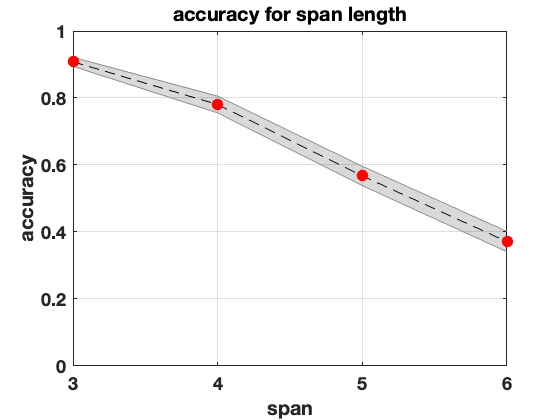

mean_span_acc = mean(span_acc);
err_span_acc = std(span_acc) / sqrt(length(span_acc));

shadedErrorBar(3:6,mean_span_acc,err_span_acc,'--k',1)
hold on
grid on
plot(3:6,mean_span_acc, ...
    '.r', ...
    'LineWidth', 2,...
    'MarkerSize',40, ...
    'MarkerFaceColor','k')  
ylim([0 1])


xlabel('span')
ylabel('accuracy')
title('accuracy for span length')
xticks([3 4 5 6])

set(gca,'FontSize',18,'fontWeight','bold')

## plot serial position

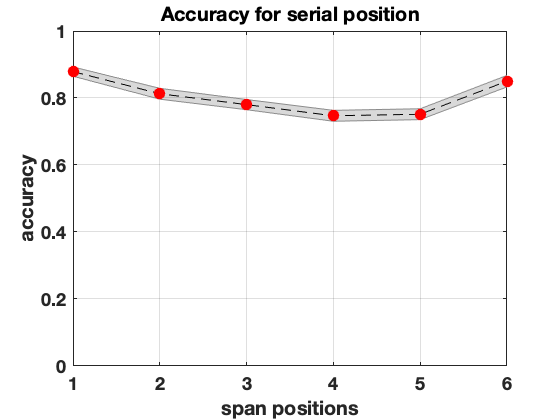

figure
mean_ser = mean(ser_pos);
err_ser = std(ser_pos) / sqrt(length(ser_pos));

shadedErrorBar(1:6,mean_ser,err_ser,'--k',1)
hold on 
grid on
plot(1:6,mean_ser, ...
    '.r', ...
    'LineWidth', 2,...
    'MarkerSize',40, ...
    'MarkerFaceColor','r')
ylim([0 1])
xlabel('span positions')
ylabel('accuracy')
title('Accuracy for serial position')
xticks([1 2 3 4 5 6])
set(gca,'FontSize',18,'fontWeight','bold')

## Histogram of subjects by span size

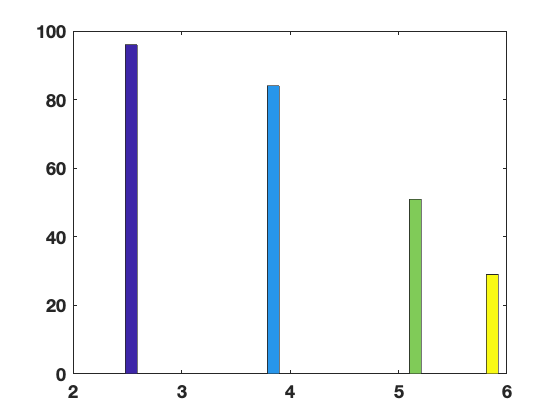

figure
hist((span_acc > .5).*[3 4 5 6])
xlim([2 6])
set(gca,'FontSize',18,'fontWeight','bold')

span_table=table(span_acc(:,1), span_acc(:,2),span_acc(:,3),span_acc(:,4), 'VariableNames', ["S3", "S4", "S5", "S6"])

span_table = 101×4 table
     S3       S4       S5       S6  
    _____    _____    _____    _____

     0.75    0.125     0.25    0.375
        1        1        1        1
    0.875      0.5      0.5     0.25
        1     0.75    0.625    0.125
     0.75     0.75    0.625        0
     0.75    0.375    0.125        0
        1      0.5      0.5    0.375
     0.75      0.5    0.125    0.125
    0.875    0.375    0.375        0
        1    0.875     0.75        0
    0.625      0.5    0.625    0.375
        1     0.75    0.625    0.125
    0.875        1    0.875      0.5
        1     0.75    0.375     0.25
        1    0.625     0.25      0.5
        1        1    0.875        1
